clc;
close all;
clear variables;

out = evalc('ziegler_nichols_frekvencijski');
clearvars -except K_znf

[L, R, C, E, x2e] = nominalni_parametri();
[G, A, B, H, ue] = linearizacija();
[Kp, Ti, Td, Tf] = PID_oblik_foo(K_znf);
s = tf('s');
Kontroler = minreal(Kp*(1 +1/Ti/s + Td*s/(Tf*s + 1)))

Kontroler =
 
  -0.127 s^2 - 27.2 s - 1493
  --------------------------
         s^2 + 4444 s
 
Continuous-time transfer function.



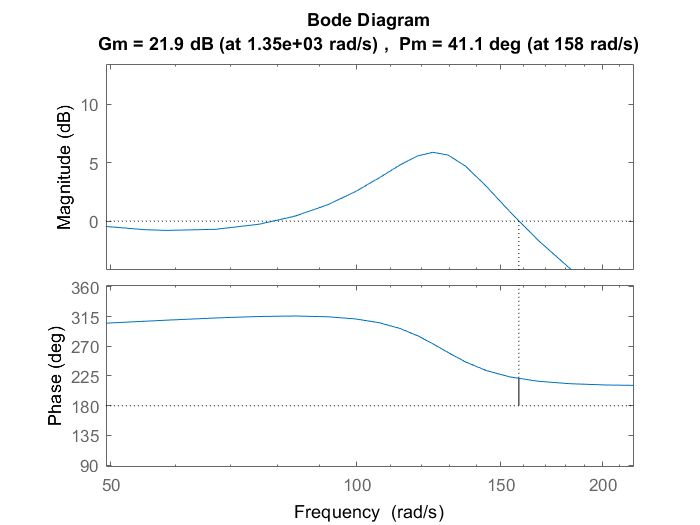

Tt = 1e-3; % s

sim_file_name = 'testiranje_kontrolera_sim';
sim_duration = 5;
open_system(sim_file_name)
sim(sim_file_name)

ans =   Simulink.SimulationOutput:

                   tout: [50001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
